# **Authors**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with ISU ID numbers.*

**Stream: [RZZZ] Technical Vision**

**Subgroup: **

Student ID 1, Name 1

Student ID 2, Name 2

Student ID 3, Name 3

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov from ITMO University in 2024.

# **Practical Assignment No 2. Images Geometric Transformations**

Studying of transformations main types and using it for spatial image correction.

## **Task 1. Simplest geometric transformations**

*Select an arbitrary image. Perform linear and nonlinear transformations over it (Eucidean, affine and projective transformations).*

### **Introduction**

Images geometric transformations imply a spatial change in the location of pixels set with integer coordinates $(x,y)$ to another set with coordinates $(x',y')$, and the pixels intensity doesn't changes. In two-dimensional plane geometric transformations, as a rule, Euclidean space is used $\mathbf{P}^2$ with an orthonormal Cartesian coordinate system. In this case, the image pixel corresponds to a pair of Cartesian coordinates, which are interpreted as a two-dimensional vector represented by a segment from a point $(0,0)$ to a point $X_i=(x_i,y_i)$. Two-dimensional transformations on a plane can be represented as the points movement corresponding to a pixels plurality.

For generality with further transformations, we will use *homogeneous coordinates*. If homogeneous coordinates of a point are multiplied by a non-zero scalar then the resulting coordinates represent the same point. Due to this the required coordinates number to represent points is always one more than the space dimension $\mathbf{P}^n$, in which these coordinates are used. For example, to represent a point $X=(x,y)$ on a plane in two-dimensional space $\mathbf{P}^2$ three coordinates are required $X=(x,y,w)$. Let's illustrate this with the following example:

$

 \left[ \matrix{ x' \cr y' \cr w} \right]= w  \left[ \matrix{ x \cr y \cr 1} \right] \Leftrightarrow 
[x', y', w] = [x, y, 1]  w
$,

where $w$ is an arbitrary scalar factor, $x=\frac{x'}{w}$, $y=\frac{y'}{w}$.

Any linear transformation of the plane can be described using triples of homogeneous coordinates and third order matrices. Thus, geometric transformations are matrix transformations, and the sets pixel coordinates of the transformed and original images are related by the following matrix relation or in a row form  $X'=XT$, or in a column form $X'=T^{\mathrm{T}}X$. Let's rewrite these relations:


$$ \left[ \matrix{ x' & y' & w'} \right] =   \left[ \matrix{ x & y & w} \right] \cdot \left[ \matrix{ A & D&G \cr B & E&H \cr C &F&I} \right] \Leftrightarrow 


 \left[ \matrix{ x' \cr y' \cr w'} \right]= \left[ \matrix{ A & B & C \cr D & E&F \cr G &H&I} \right] \cdot \left[ \matrix{ x \cr y \cr w} \right].$$


Point with Cartesian coordinates $(x,y)$ in homogeneous coordinates is written as $(x,y,1)$:


$$\matrix{\left[x' & y' & 1 ] } =   \left[ \matrix{ x & y & 1} \right] \cdot \left[ \matrix{ A & D&0 \cr B & E&0 \cr C &F&1} \right] \Leftrightarrow 


 \left[ \matrix{ x' \cr y' \cr 1} \right]= \left[ \matrix{ A & B & C \cr D & E&F \cr 0 &0&1} \right] \cdot \left[ \matrix{ x \cr y \cr 1} \right].$$


So, the transformation formula  can be rewritten as following system equations:


$$\begin{cases}
		x'=Ax+By+C, 
		\\ y'=Dx+Ey+F
	\end{cases}.$$


### **1.1 Preparation**

First, we need to clear Command window and Workspace.

clc
clear all

### **1.2 Read and display an image**

Now let's open our image which we will use during the current task using ````imread(I)` `function. We will open it in RGB mode. We can convert RGB image to grayscale by calling ``rgb2gray(I)`` funtion. For estimating grayscale image size we may use ``size(Igray)` `function, that returns three parameters: number of rows, number of columns and number of layers. For displaying it we may use ``montage()`` function.

% Read an image from file 
% and display its grayscale representation
I = imread('lena_color.png');
Igray = rgb2gray(I);
[numRows, numCols, Layers] = size(Igray);
montage({I,Igray});

### **1.3 Linear transformations**

**Linear transformation** (also called **Linear mapping**) $-$ is a mapping that preserves the infinitesimal figures shape and the angles between curves at their intersection points. The main linear mapping are Euclidean transformations. These transformations include shift, flip, uniform scaling, and rotation. Linear transformations are a affine transformations subset.

#### **1.3.1 Image shift**

The simplest image transformation is an image shift. System equations and coordinates transformation matrix $T$ in case of image *shift* $A=E=1,$ $B=D=0$ take the form:


$$    \begin{cases}
        x'=x+C \\
        y'=y+F
    \end{cases} ,$$


which can be also written in the vertor form:

$[x', y', 1] = [x, y, 1]  T$,

and gives us a very simple transformation matrix:


$$T= \left[ \matrix{1 & 0&0 \cr 0 & 1&0 \cr C &F&1} \right],

$$


where $C$ and $F$ are the shift values along axes $Ox$ and $Oy$ correspondingly.

As we use MATLAB, we may define this matrix in the following form:


$$T= \left[ \matrix{1 & 0 \cr 0 & 1 \cr C & F } \right],

$$


In MATLAB implementation the transformation matrix is a sarray with dimensions $2\times3$, so it can be created by typing ``T = [1 0; 0 1; C F]``. Then, the ``tform = affine2d(T)`` should be used for setting transformation matrix. After that you need to use ``imwarp()`` function to perform the affine transformation. Its first argument is an image to transform, the second one is the transformation matrix and the third one is some extra parameters for displaying the resulting image. It returns a transformed image as a result. As the image resolution may be changed during the image trnasformation, this could be accounted and given as a third image parameter. In case of image shift, the resulution is changed by the shift value, so we will account this by increasing the image size.

First, let's try shifting an image without setting the desired transformed image resolution.

% Create transformation matrix and call cv.warpAffine
C = 50;
F = 100;
T = [1 0; 0 1; C F];
tform = affine2d(T);
I_shift = imwarp(Igray, tform);

% Display it
imshow(I_shift);

As you can see, we don't have some changes, because ``imshow()`` function tryies to center output image. To correct it we should use a third parameter in the ``imwarp()`` function. Let's account for it as well.

I_shift2 = imwarp(Igray, tform, 'Interp', 'nearest', ...
   'OutputView', imref2d([numRows, numCols, Layers], [1 numCols], [1 numRows]));
figure;
imshow(I_shift2);

As you see now the image is shifted.

# ***Self-work***

**Shift an image to the left and up by **$(-50, -100)$**.**

% TODO Place your solution here
% Ishift3 = ;






#### **1.3.2 Image flip**

The transformation equation and coordinates transformation matrix $T$ parameters in case of *image flip* around the axis $Ox$ (along axis $Oy$) are $A=1$, $E=-1$, $B=C=D=F=0$. Then equations and matrix will take the form:


$$\begin{cases}
		x'=x \\
		y'=-y
	\end{cases} 
	\Rightarrow

T= \left[ \matrix{1 & 0 & 0 \cr  0 & -1 & 0 \cr 0 & 0 & 1 } \right].$$


In case of MATLAB the transformation matrix could be defined as:


$$T= \left[ \matrix{1 & 0 \cr 0 &  -1 \cr 0 & 0 } \right].$$


And vice versa. The transformation equation and coordinates transformation matrix $T$ parameters in case of *image flip* saround the axis $Oy$ (along axis $Ox$) are $A=-1$, $E=1$, $B=C=D=F=0$. Then equations and matrix will take the form:


$$\begin{cases}
		x'=x \\
		y'=-y
	\end{cases} 
	\Rightarrow

T= \left[ \matrix{-1 & 0 & 0 \cr  0 & 1 & 0 \cr 0 & 0 & 1 } \right].$$


In case of MATLAB the transformation matrix could be defined as:


$$T= \left[ \matrix{-1 & 0 \cr 0 &  1 \cr 0 & 0 } \right].$$


Let's run it.

% Flip around Oy
T = [1 0; 0 -1; 0 0];
tform = affine2d(T);
I_flipy = imwarp(Igray, tform);

% Flip around Ox
T = [-1 0; 0 1; 0 0];
tform = affine2d(T);
I_flipx = imwarp(Igray, tform);

% Display it
figure;
montage({Igray, I_flipy, I_flipx});

MATLAB also provides a functions for fast flipping arrays: ``flipud()`` $-$ flips array in the up-down direction, and ``fliplr()`` $-$ flips array in the left-right direction. It can takes one parameter as an image array to flip. 

Let's try doing the same flip with MATLAB built-in function.

% Flip around Oy
I_flipx2 = fliplr(Igray);

% Flip around Ox
I_flipy2 = flipud(Igray);

% Display it
figure;
montage({Igray, I_flipy, I_flipx});

# ***Self-work***

**Flip an image along both axis (**$Ox$** and **$Oy$**). Implement two solutions:**

**1. Create the transformation matrix and apply it with **``imwarp()``** function (you may either create a single transformation matrix or apply transformation two times: for **$Ox$** and **$Oy$** axes);**

**2. Use the MATLAB built-in `**`flipud()`**` and **``fliplr()``** functions.**

**Compare the results, they should match.**

% TODO Place your solution for part 1 here
% Create a matrix for flip (either one matrix for single flip or two matrices for flip around Ox and around Oy)
% Apply the transformation with imwarp() function
% Display the result

% I_flipxy = 

% TODO Place your solution for part 2 here
% Flip the image with `flipud()` and `fliplr()` functions
% Display the result

% I_flipxy2 = 

Did your rotation results match? Don't forget to check it. There might be a little difference due to a different floating point values processing.

#### **1.3.3 Uniform image scale**

The transformation equation and coordinates transformation matrix $T$ parameters in case of *image scale* by $\alpha$ along $Ox$ axis and $\beta$ along $Oy$ axis are $A=\alpha$, $E=\beta$, $B=C=D=F=0$. Then equations and matrix will take the form:


$$\begin{cases}
		x'=\alpha x, \alpha>0 \\
		y'=\beta y, \beta >0
	\end{cases} 
	\Rightarrow


T= \left[ \matrix{\alpha & 0 & 0 \cr  0 & \beta & 0 \cr 0 & 0 & 1 } \right].$$


If $\alpha<1$ and $\beta<1$, then the image decreases in size, if $\alpha>1$ and $\beta>1$ then it increases. If $\alpha \ne \beta$, then the proportions will not be the same in width and height. In general, this mapping will be affine, not linear.

In case of using MATLAB the transformation matrix could be defined as:


$$T= \left[ \matrix{\alpha & 0 \cr  0 & \beta \cr 0 & 0 } \right].
$$


% Image scale
alfa = 0.5;
beta = 0.5;
T = [alfa 0; 0 beta; 0 0];
tform = affine2d(T);
I_scale = imwarp(Igray, tform, 'Interp', 'nearest', ...
   'OutputView', imref2d([numRows, numCols, Layers], [1 numCols], [1 numRows]));
figure;
montage({Igray,I_scale});

MATLAB also provides function called ``imresize()`` to resize an image in a single command. We may use it as well.

% Image scale
I_scale2 = imresize(Igray,alfa,'nearest');
figure;
montage({Igray,I_scale});

# ***Self-work***

**Scale an image to upscale it by one and a half times (scale factor **$1.5$** along both axes). Implement two solutions:**

**1. Create the transformation matrix and apply it with **``imwarp()``** function;**

**2. Use the MATLAB built-in **``imresize()``** function.**

**Compare the results, they should match. Don't forget that this transformation should change the image size.**

% TODO Place your solution for part 1 here
% Create matrix for scale
% Apply transformation with imwarp() function
% Display the result

% I_scale15 = 

% TODO Place your solution for part 2 here
% Scale the image with imresize() function
% Display the result

% Iscale15_2 = 

Did your rotation results match? Don't forget to check it. There might be a little difference due to a different floating point values processing.

#### **1.3.4 Image rotate**

The transformation equation and coordinates transformation matrix $T$ parameters in case of *image rotation* by $\varphi$ degree clockwise around the coordinate system center are $A=\cos \varphi$, $B=-\sin \varphi$, $D=\sin \varphi$, $E=\cos \varphi$, $C=F=0$. Then equations and matrix will take the form:


$$\begin{cases}
		x'=x \cos \varphi - y \sin \varphi \\
		y'= x \sin \varphi + y \cos \varphi
	\end{cases} 
	\Rightarrow


T= \left[ \matrix{\cos \varphi & \sin \varphi & 0 \cr  -\sin \varphi & \cos \varphi & 0 \cr 0 & 0 & 1 } \right].$$


If $\varphi = 90^{\circ}$, then $\cos \varphi = 0$ and $\sin \varphi = 1$ and transformation equation take the form:


$$	\begin{cases}
		x'=-y \\
		y'=x
	\end{cases} 
	\Rightarrow 


T= \left[ \matrix{0 & 1 & 0 \cr  -1 & 0 & 0 \cr 0 & 0 & 1 } \right].$$


In case of using MATLAB the transformation matrix should be defined as:


$$
T= \left[ \matrix{\cos \varphi & \sin \varphi \cr  -\sin \varphi & \cos \varphi \cr 0 & 0 } \right].

$$


Let's do it.

% Image rotation
phi = 17 * pi / 180; % angle should be defined in radians
T = [ cos(phi) sin(phi);
      -sin(phi) cos(phi);
             0        0];
tform = affine2d(T);
I_rotate = imwarp(Igray, tform, 'Interp', 'nearest', ...
   'OutputView', imref2d([numRows, numCols, Layers], [1 numCols], [1 numRows]) );
figure;
imshow(I_rotate);

The image is really rotated arount the coordinate system center which is top left corner, however in general we would like to rotate it around an arbitrary point. To do it, the rotations should be defined as a set of image transformations which are:

1. Shift an image so that the rotation point is in the top left corner;

2. Rotate it with a given angle;

3. Shift it back. 

This can be written in a matrix form and then executed as a single affine transformation:


$$
T_{shift}= \left[ \matrix{1 & 0 & 0  \cr  0 & 1 & 0  \cr - numCols / 2& -numRows/2 & 1 } \right],$$



$$
T_{rotate}= \left[ \matrix{\cos \varphi &  \sin \varphi & 0 \cr - \sin \varphi  & \cos \varphi  & 0  \cr 0& 0 & 1 } \right],$$



$$
T_{shiftback}= \left[ \matrix{1 & 0 & 0  \cr  0 & 1 & 0  \cr numCols/2& numRows/2 & 1 } \right].$$


Here $T_{shift}$ matrix is a forward shift to match $(0, 0)$ with image center, $T_{rotate}$ is rotation matrix, and $T_{shiftback}$ is backward shift to move image back to place after rotation. Then the final transformation matrix $T$ is calculated by multiplying these three transformation matrices and taking two first rows from it.


$$T = T_{shiftback} \cdot T_{rotate} \cdot T_{shift}.$$


Let's implement it with MATLAB and rotate our image aroud its center.

% Image rotation
phi = 17 * pi / 180; % angle should be defined in radians
Tshift = [                 1                     0    0; 
                           0                     1    0;
          -round(numCols / 2)   -round(numRows / 2)   1];
Trotate = [  cos(phi)    sin(phi)    0;
            -sin(phi)    cos(phi)    0;
                    0           0    1];
Tshiftback = [                1                     0    0; 
                              0                     1    0;
              round(numCols / 2)    round(numRows / 2)   1];
T = Tshift * Trotate * Tshiftback;

tform = affine2d(T);
I_rotate2 = imwarp(Igray, tform, 'Interp', 'nearest', ...
   'OutputView', imref2d([numRows, numCols, Layers], [1 numCols], [1 numRows]) );
figure;
imshow(I_rotate2);

Finally, MATLAB ``imrotate()`` function can be used to rotate an image in a counterclockwise direction around its center point.

Let's try it too.

% Image rotation around image center
phi = 17.0; % here we use degrees to define an angle
I_rotate3 = imrotate(Igray,phi,'nearest');

% Display it
figure;
imshow(I_rotate3);

# ***Self-work***

**1. Rotate an image around the center of the bottom left quarter with coordinates **$(\frac{1}{4} \cdot width, \frac{3}{4} \cdot height)$** by 45**°** clockwise. Create the rotation matrix manually with three matrices.**

**2. Rotate an image around the center using the MATLAB built-in **``imrotate()``** function for rotation.**

% TODO Place your solution for part 1 here
% Create matrices for shift, rotation and shift back
% Multiply these matrices
% Apply transformation with imwarp() function
% Display the result

% Irotate45 = 


% TODO Place your solution for part 2 here
% Apply transformation with imrotate() function
% Display the result

% Irotate45_2 = 



#### **1.3.5 Arbitrary affine transformation**

**Affine mapping** is a mapping, in which parallel lines go into parallel lines, intersect lines into intersect lines, cross lines into cross lines; the segments lengths ratios of lying on the one straight line (or on parallel lines) are preserved, and the figures areas ratios are preserved also. Basic transformations are linear transformations, bevel and non-uniform scaling. An arbitrary affine transformation can be obtained using the sequential product of the basic transformation matrices. In continuous geometry, any affine transformation has an inverse affine transformation, and the product of the direct and inverse transformations gives a unit transformation that leaves all points in place without changing. Affine transformations are a subset of projection transformations.

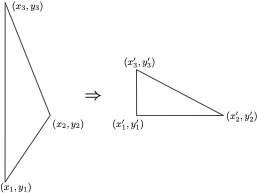

`Affne mapping`

Such transformation can be defined by three pairs of points and then the transformation matrix will be calculated from a linear equations system. Let us assume we have three pairs of matching points: $P_{src} = \lbrace(x_1, y_1), (x_2, y_2), (x_3, y_3)\rbrace$ which matches $P_{dst} = \lbrace(x'_1, y'_1), (x'_2, y'_2), (x'_3, y'_3)\rbrace$. Then after substitution to the thansformation equiations we will get:


$$  \begin{cases}

    x'_1 = x_1 \cdot A + y_1 \cdot B + C \\
    y'_1 = x_1 \cdot D + y_1 \cdot E + F \\
    x'_2 = x_2 \cdot A + y_2 \cdot B + C \\
    y'_2 = x_2 \cdot D + y_2 \cdot E + F \\
    x'_3 = x_3 \cdot A + y_3 \cdot B + C \\
    y'_3 = x_3 \cdot D + y_3 \cdot E + F
  \end{cases}.$$


Which gives us six linear equations with 6 varibales. Solving these equations will give us the transoformation matrix. To do it, the ``estgeotform2d()`` function can be used, it takes 3 pairs of points as argumnts and returns the corresponding transformation matrix. For applying transformation matrix to a polygon you may use the function ``transformPointsForward()``.

% Common points
Psrc = [50 300; 150 200; 50 50];
Pdst = [50 200; 250 200; 50, 100];

% Calculate the transformation matrix
tform = estgeotform2d(Psrc,Pdst,'affine');
polygon = [[Psrc(:,1); Psrc(1,1)], [Psrc(:,2); Psrc(1,2)]];
Iaffine = transformPointsForward(tform, polygon); 

% Draw trinangles on source and transformed images and display it
figure;
subplot(2,2,1);
line(polygon(:, 1), polygon(:, 2),'Color',  'red', 'LineStyle','-', 'LineWidth',3);
subplot(2,2,2);
line(Iaffine(:, 1), Iaffine(:, 2), 'Color', 'blue','LineStyle','-', 'LineWidth',3);

# ***Self-work***

**Implement the backward transformation of the**` `Iaffine``** image. The transformation should use **``Pdst``** points as a source data and **``Psrc``** points as the destination. Transformed image should match the source image.**

% TODO Place your solution here
% Calculate the transformation matrix for transformation from Pdst to Psrc
% Apply transformation with transformPointsForward() function
% Display the result




#### **1.3.6 Image bevel**

The transformation equation and coordinates transformation matrix $T$ parameters in case of *image bevel* by factor $s$ along $Ox$ axis are $A=E=1$, $B=s$, $C=D=F=0$. Then equations and matrix will take the form:


$$	\begin{cases}
		x'=x+sy, \\
		y'=y,
	\end{cases}
	\Rightarrow 


T= \left[ \matrix{1 & 0 & 0 \cr  s & 1 & 0 \cr 0 & 0 & 1 } \right].

$$


With MATLAB this will give us the following transformation matrix:


$$T= \left[ \matrix{1 & 0 \cr  s & 1 \cr 0 & 0 } \right].$$


We know how to implement it. Let's do it.

# ***Self-work***

**Implement the image bevel transformation according with the matrix above with **$s = 0.3$** and run it.**

% TODO Place your solution here
%Ibevel = 






#### **1.3.7 Piecewise linear mapping**

In some cases we don't need to transform the whole image. *Piecewise-Linear Mapping* is a mapping in which the image is split into parts, and then various linear transformations are applied to each of these parts separately.

Let's try using piecewise linear mapping to scale the right half of an image.

% Piecewise linear mapping
stretch = 2;
T = [stretch 0 0; 0 1 0; 0 0 1];
tform = affine2d(T);

% Split image
imid = round(numCols / 2);
I_left = Igray(:,1:imid,:);
I_right = Igray(:,(imid+1:end),:);

% Transform right part and stitch
I_scale2 = imwarp(I_right, tform);
I_plm = [I_left I_scale2];

% Display the result
figure
imshow(I_plm);

# ***Self-work***

**Implement the piecewise linear mapping transformation and scale the right part of an image with scale factor **$0.5$**.**

% TODO Place your solution here
% Fill the transformation matrix
% Split and display image parts
% Transform right part and stitch
% Display the result

%Iplm2 = 


### **1.4 Nonlinear transformations**

When considering geometric transformations, it is assumed that the images were obtained using an ideal camera model. In fact, imaging is accompanied by various nonlinear distortions. So, the nonlinear functions are used to correct them.

*Nonlinear distortion examples*

#### **1.4.1 Perspective mapping**

**Perspective mapping** is a mapping, in which straight lines remain straight lines, however, the figure geometry may be distorted, because this mapping generally does not preserve the lines parallelism. The property preserved under this mapping is points *collinearity*: three points lying on one straight line (collinear) remain on one straight line after mapping. Projection mapping can be as *parallel* (scale is changed), and *perspective* (the figure geometry is changed). 

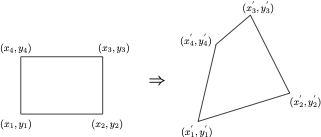

*Perspective mapping: straight lines remain straight, but parallel ones may intersect*

In the case of a perspective mapping a three-dimensional scene point $\mathbf{P}^3$ projected onto a two-dimensional image plane $\mathbf{P}^2$. This mapping $\mathbf{P}^3 \to \mathbf{P}^2$ maps the scene Euclidean point $P=(x,y,z)$ (in homogeneous coordinates $(x',y',z',w)$) in the image point $X=(x,y)$ (in homogeneous coordinates $(x',y',w)$). To find the points Cartesian coordinates from homogeneous coordinates, we use the following relations: $P=(\frac{x'}{w}, \frac{y'}{w}, \frac{z'}{w})$ $-$ are coordinates of the vector $\vec P$ and $X=(\frac{x'}{w}, \frac{y'}{w})$ $-$ are coordinates of the vector $\vec X$. Substituting $w=1$ for vector $\vec X$ we obtain the equations system:


$$	\begin{cases}
		x'=\frac{Ax+By+C}{Gx+Hy+I}, \\
		y'=\frac{Dx+Ey+F}{Gx+Hy+I},
	\end{cases}
	\Rightarrow 


T= \left[ \matrix{A & B & C \cr  D & E & F \cr G & H & 1 } \right]

$$


Due to the coordinates normalization to $w$ in general, the projection mapping is nonlinear.

With MATLAB we can define projective transformation matrix same as we did for the affine transformtaion, then use the ``imwarp()`` function with ``projective2d()`` function for setting transformation matrix.

% Perspective transformation
T = [1.1 0.2 0.00075; 0.35 1.1 0.0005; 0 0 1];
tform = projective2d(T);
Iproj = imwarp(Igray, tform);

% Display it
figure;
montage(Iproj);

MATLAB also provides a handy ``estgeotform2d(Psrc,Pdst,'affine')`` function for the projective transformation matrix calculation for an arbitrary projection mapping can be calculated by specifying the coordinates of four source points $P_{src} = \lbrace(x_1, y_1), (x_2, y_2), (x_3, y_3), (x_4, y_4)\rbrace$ and their coordinates after transformation $P_{dst} = \lbrace(x'_1, y'_1), (x'_2, y'_2), (x'_3, y'_3), (x'_4, y'_4)\rbrace$. It works a way similar as calculation of an affine trnasformation matrix: solves the system of linear equations.

Let's try it.

% Perspective transformation
Psrc = [50 461; 461 461; 461 50; 50 50];
Pdst = [50 461; 461 440; 450 10; 100 50];
tform = estgeotform2d(Psrc,Pdst,'projective');
polygon = [[Psrc(:,1); Psrc(1,1)], [Psrc(:,2); Psrc(1,2)]];
Iproj2 = transformPointsForward(tform, polygon);

% Draw points on source and transformed images, and display it
figure;
subplot(2,2,1);
line(polygon(:, 1), polygon(:, 2),'Color',  'red', 'LineStyle','-', 'LineWidth',3);
subplot(2,2,2);
line(Iproj2(:, 1), Iproj2(:, 2),  'Color',  'blue','LineStyle','-', 'LineWidth',3);

# ***Self-work***

**Implement the backward perspective transformation of the **``Iproj2``** image. The transformation should use **``Pdst``** points as a source data and **``Psrc``** points as the destination. Transformed image should match the source image.**

% TODO Place your solution here
% Calculate the perspective transformation matrix for transformation from Pdst to Psrc
% Apply the perspective transformation with transformPointsForward() function
% Display the result

% Iproj3 = 


#### **1.4.2 Polynomial mapping**

**Polynomial mapping** is an original image mapping using polynomials. In this case, the coordinate transformation matrix $T$ will contain the polynomials coefficients of the corresponding orders for the coordinates $x$ and $y$. For example, in case of polynomial mapping of the *second order* equations system takes the following form:


$$    \begin{cases}
        x'=a_1+a_2x+a_3y+a_4x^2+a_5xy+a_6y^2 \\
        y'=b_1+b_2x+b_3y+b_4x^2+b_5xy+b_6y^2
    \end{cases},$$


where $x$, $y$ are the point coordinates in one coordinate system, and $x'$, $y'$ are points coordinates in another coordinate system, $a_1 \dots a_6$, $b_1 \dots b_6$ are the mapping coefficients. MATLAB has no built-in function for such kind of transformatios.

Let's implement a polynomial mapping with a given transformation coefficient as a matrix $T$:


$$    \begin{cases}
x' = 0 + 1 \cdot x + 0 \cdot y + 0.00001 \cdot x^2 + 0.002 \cdot x y + 0.001 \cdot y^2
\\
y' = 0 + 0 \cdot x + 1 \cdot y + 0 \cdot x^2 + 0 \cdot x y + 0 \cdot y^2
\end{cases}.$$


% Polynomial mapping
T = [      0 0; 
           1 0; 
           0 1; 
     0.00001 0;
       0.002 0; 
       0.001 0];
    for y=1:1:numCols
        for x=1:1:numRows
            xnew = round(T(1,1)         + T(2,1) * x   + ...
                         T(3,1) * y     + T(4,1) * x^2 + ...
                         T(5,1) * x * y + T(6,1) * y^2   ...
            );
            ynew = round(T(1,2)         + T(2,2) * x   + ...
                         T(3,2) * y     + T(4,2) * x^2 + ...
                         T(5,2) * x * y + T(6,2) * y^2   ...
            );
            Ipoly(xnew, ynew) = Igray(x,y);
        end
    end

% Display it
figure;
imshow(Ipoly);

Since not every pixel on the new image has the corresponding pixel color value the black areas appeared. It can be converted by interpolating the missing pixel values using the known ones.

# ***Self-work***

**Implement the polynomial mapping of the source image with following formula:**

$x' = 0 + 1 \cdot x + 0 \cdot y + 0 \cdot x^2 + 0 \cdot x y + 0 \cdot y^2$,

$y' = 0 + 0 \cdot x + 1 \cdot y + 0.001 \cdot x^2 + 0.002 \cdot x y + 0.00001 \cdot y^2$.

% TODO Place your solution here
% Fill the polynomial mapping parameters array
% Calculate new coordinates for X, Y according to formula
% Display the result

% Ipoly2 = 

  

#### **1.4.3 Sinusoidal distortion**

Harmonic distortion of an image can be considered as another example of nonlinear transformation.

Let's try creating the sinusoidal distortion. For this we will use OpenCV remapping feature whih allows to remap the whole image by defining the pixel coordinates in the source coordinate system for each pixel of the transformed image. This is implemented by the ``remap()`` function which transforms image according to new pixel coordinates specified for each pixel of the source image.

Let's apply the sinusoidal distortion along $Ox$ axis.

% Create mesh grid for X, Y coordinates
[xi,yi] = meshgrid(1:numCols, 1:numRows);

% Distort the X coordinate depending on Y
u = xi + 20 * sin(2 * pi * yi / 90);
v = yi;

% Remap with new coordinates
tmap_B = cat(3,u,v);
resamp = makeresampler('linear', 'fill');
Isin_x = tformarray(Igray, [], resamp, [2 1], [1 2], [], tmap_B, 0.3);

% Display it
figure;
imshow(Isin_x);

# ***Self-work***

**Implement the sinusoidal distortion along **$Oy$** axis with same parameter values.**

% TODO Place your solution here
% Create mesh grid for X, Y coordinates
% Distort the Y coordinate depending on X
% Remap with new coordinates
% Display the result

%Isin_y = 
  


## **Task 2. Distortion correction**

*Select an arbitrary image with either pincushion or barrel distortion. Correct the image.*

When the optical system is forming an image, *distortion* may occur on the image. 

**Distortion** is an optical distortion that is expressed in the curvature of straight lines. Light rays passing through the center of the lens converge at a point farther from the lens than rays passing through the edge of the lens. Straight lines are curved, except for those that lie in the same plane with the optical axis. For example, the image of a square, the center of which intersects the optical axis, looks like a pillow (*pincushion distortion*) with positive distortion and looks like a barrel (*barrel distortion*) with negaitive distortion.

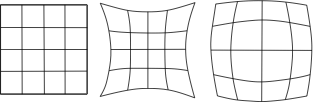

*Distortions examples. Left is the original image, center is a pincushion distortion, right is a barrel distortion*

Let $\vec{r}=(x,y)$ $-$ vector specifying two coordinates in a plane perpendicular to the optical axis. For an ideal image, all rays leaving this point and passing through the optical system will hit the image point with coordinates $\vec{R}$, which are determined by the formula:


$$\vec{R}=b_0\vec{r},$$


where $b_0$ is a linear increasing parameter.

If distortion of a higher order is present (for axisymmetric optical systems, the distortion can only be of odd orders: third, fifth, seventh, etc.), then it is necessary to add the appropriate terms:


$$\vec{R}=b_0\vec{r}+F_3r^2\vec{r}+F_5r^4\vec{r}+\dots,$$


where $r$ is the vector length $\vec{r}$; $F_i, i=3,5,\dots,n$ are the distortion coefficients of $n$-th order, which contribute the most to the distortion of the image shape. With third-order distortion, if the coefficient $F_3$ has the same sign as $b_0$: $sign(F_3)=sign(b_0)$, pincushion distortion occurs, otherwise a barrel distortion occurs. 

To correct the distortion, the approach described above for affine of projective transformation is used. An image of a regular grid and its distorted image is used, pairs of points on these images are found, and the coefficients of the corrective transformation are calculated.

### **2.1 Barrel distortion**

To distort an image we will do the following steps:

1. First, create a **`meshgrid`** for our image pixel coordinates;

2. Then shift the mesh coordinates so that image center has coordinates $(0, 0)$ and transform them to a polar coordinate system;

3. Apply distortion transformation in the polar coordinate system;

4. Convert mesh coordinates back to Cartesian coordinate system and shift back;

5. Remap an image with the calculated mesh map.

Let's distort an image according to formula:


$$\vec{R}=\vec{r} + 0.1 \cdot r^2\vec{r} + 0.12 \cdot r^4\vec{r}.$$


% Barrel distortion
% Create a mesh grid for X, Y coordinates
[xi, yi] = meshgrid(1:numCols, 1:numRows);
xmid = round(numCols / 2);
ymid = round(numRows / 2);
xt = xi(:) - xmid;
yt = yi(:) - ymid;

% Convert to polar coordinates
[theta, r] = cart2pol(xt,yt);

% Set of parameters
rmax = max(r(:));
b0 = 1;
F3 = 0.1;
F5 = 0.12;
R = b0 * r + F3 * r .^ 3 / rmax .^ 2 + F5 * r .^ 5 / rmax .^ 4;

% Convert back to Cartesian coordinates
[ut, vt] = pol2cart(theta, R);
u = reshape(ut, size(xi)) + xmid;
v = reshape(vt, size(yi)) + ymid;

% Obtaining a map for distortion
tmap_B = cat(3, u, v);

% Applying the map to the image
resamp = makeresampler('linear', 'fill');
Ibarrel = tformarray(Igray, [], resamp, [2 1], [1 2], [], tmap_B, 0.3);

% Display it
figure;
imshow(Ibarrel);

To correct the distortion we need to define a set of matching points on both distored and corrected image. We will calculate these points along radius in polar coordinate system assuming they were defined by user.

% Calculate the set of matching points
d = 5;          % Number of points
max_r = 1;      % Points array scale
Psrc = (1:d) / d * max_r;
Pdst = Psrc + F3 * (Psrc .^ 3) / rmax .^ 2 + F5 * (Psrc .^ 5) / rmax .^ 4;

% Now create and fill matrix for linear equiations 
% with degrees of dst radiuses
% and invert it
T = zeros(d, d);
for i = 1:d
    T(:, i) = Pdst'.^(i);
end
F = inv(T) * Psrc';

% Convert to polar coordinates again
[theta, r_distorted] = cart2pol(xt, yt);

% Calculate the new radial distance
r_corrected = zeros(size(r_distorted));
for i = 1:d
    r_corrected = r_corrected + F(i) * (r_distorted .^ i);
end

% Convert back to Cartesian coordinates
[ut_corr, vt_corr] = pol2cart(theta, r_corrected);
u_corr = reshape(ut_corr, size(xi)) + xmid;
v_corr = reshape(vt_corr, size(yi)) + ymid;

% Obtaining a map for the correction procedure
tmap_corr = cat(3, u_corr, v_corr);

% Applying the map to the distorted image and displaying it
Ibarrel_corr = tformarray(Ibarrel, [], resamp, [2 1], [1 2], [], tmap_corr, 0.3);
figure;
subplot(1, 2, 1);
imshow(Ibarrel);
title('Barrel distortion');
subplot(1, 2, 2);
imshow(Ibarrel_corr);
title('Distortion correction');

# ***Self-work***

**Distort an image according with formula **$\vec{R}=\vec{r} -0.2 \cdot r^2\vec{r} + 0.32 \cdot r^4\vec{r}$** and correct the distortion.**

% TODO Place your solution here







### **2.2 Pincushion distortion**

The pincustion distortion is calculated a similar way but with different parameters. 

Let's distort an image according to formula:


$$\vec{R}=1.3 \cdot \vec{r} - 0.15 \cdot r^2\vec{r}.$$


% Create mesh grid for X, Y coordinates
[xi, yi] = meshgrid(1:numCols, 1:numRows);
xmid = round(numCols / 2);
ymid = round(numRows / 2);
xt = xi(:) - xmid;
yt = yi(:) - ymid;
[theta, r] = cart2pol(xt,yt);
rmax = max(r(:));
b0 = 1.3;
F3 = -0.15;
F5 = 0;
R = b0 * r + F3 * r .^ 3 / rmax .^ 2 + F5 * r .^ 5 / rmax .^ 4;
[ut, vt] = pol2cart(theta, R);
u = reshape(ut, size(xi)) + xmid;
v = reshape(vt, size(yi)) + ymid;
tmap_B = cat(3, u, v);
resamp = makeresampler('linear', 'fill');
Ipincushion = tformarray(Igray, [], resamp, [2 1], [1 2], [], tmap_B, 0.3);

% Display it
figure;
imshow(Ipincushion);

Let's correct this one as well.

% Calculate the set of matching points
d = 5;          % Number of points
max_r = 1;      % Points array scale
Psrc = (1:d) / d * max_r;
Pdst = Psrc + F3 * (Psrc .^ 3) / rmax .^ 2 + F5 * (Psrc .^ 5) / rmax .^ 4;

% Now create and fill matrix for linear equiations 
% with degrees of dst radiuses
% and invert it
T = zeros(d, d);
for i = 1:d
    T(:, i) = Pdst'.^(i);
end
F = inv(T) * Psrc';

% Convert to polar coordinates again
[theta, r_distorted] = cart2pol(xt, yt);

% Calculate the new radial distance
r_corrected = zeros(size(r_distorted));
for i = 1:d
    r_corrected = r_corrected + F(i) * (r_distorted .^ i);
end

% Convert back to Cartesian coordinates
[ut_corr, vt_corr] = pol2cart(theta, r_corrected);
u_corr = reshape(ut_corr, size(xi)) + xmid;
v_corr = reshape(vt_corr, size(yi)) + ymid;

% Obtaining a map for the correction procedure
tmap_corr = cat(3, u_corr, v_corr);

% Applying the map to the distorted image and displaying it
Ipincushion_corr = tformarray(Ipincushion, [], resamp, [2 1], [1 2], [], tmap_corr, 0.3);
figure;
subplot(1, 2, 1);
imshow(Ipincushion);
title('Pincushion distortion');
subplot(1, 2, 2);
imshow(Ipincushion_corr);
title('Pincushion correction');

It can be seen this image is also corrected. Black areas appeared because of data loss when the distortion was applied.

# ***Self-work***

**Distort an image according with formula **$\vec{R}=1.2 \cdot \vec{r} - 0.2 \cdot r^2\vec{r} + 0.05 \cdot r^4\vec{r}$** and correct the distortion.**

% TODO Place your solution here







## **Task 3. Stitching images**

Select two images (photographs from a camera, fragments of a scanned image, etc.) which have an overlapping area. Correct the second image to translate it into the coordinate system of the first one; then perform automatic *"gluing"* from two images into the one.

Geometric transformations can be used, for example, to create mosaics from multiple images. Mosaic *"stitching", "gluing")* is the combination of two or more images into a single one, and the images coordinate systems  being glued may differ due to different shooting angles, changes in the camera position or the object movement. However, it is necessary that both images have overlapping areas, i.e. they were attended by the same objects.

### **3.1 Manual image stitching**

The main task of processing such images is to bring them into a common coordinate system. As a common coordinate system, you can use the system of the first image, then you need to find the coordinate transformation of all pixels of the second image $(x,y)$ to the common coordinate system $(x',y')$. If there is a projective distortion, then to recalculate the coordinates, you can use the projective transformation. In the case of an affine mapping, the transformation takes the form:


$$	\begin{cases}
		x'=a_1+a_2x+a_3y \\
		y'=b_1+b_2x+b_3y
	\end{cases},$$


Therefore, it is only necessary to find only 3 parameters for each coordinate:


$$ \left[ \matrix{a_{1} \cr a_{2} \cr a_{3} } \right] = 


 \left[ \matrix{1 & x_{1} & y_{1} \cr  1 & x_{2} & y_{2} \cr 1 & x_{3} & y_{3} } \right]^{-1}

 \left[ \matrix{x_{1}' \cr x_{2}' \cr x_{3}'  } \right],$$



$$ \left[ \matrix{b_{1} \cr b_{2} \cr b_{3} } \right] = 


 \left[ \matrix{1 & x_{1} & y_{1} \cr  1 & x_{2} & y_{2} \cr 1 & x_{3} & y_{3} } \right]^{-1}

 \left[ \matrix{y_{1}' \cr y_{2}' \cr y_{3}'  } \right].$$


To do this we will search for a correlation between two images. We will take severla bottom rows of the first image and serach for a correlation of these rows in a second image.

In MATLAB the correlation between two arrays and it is calculated with ``corr2()`` function. This functions returns the correlation coefficient between two input arrays. `We need `to select the highest correlation point and shift the second image by this value before merging.

Let's do it.

% Read the images from files and estimate its sizes
topPart = im2double(rgb2gray(imread('lena_top.png')));
botPart = im2double(rgb2gray(imread('lena_bottom.png')));
[numRowsTop, numColsTop] = size(topPart);
[numRowsBot, numColsBot] = size(botPart);

% Show parts of image
figure;
subplot(2,1,1);
imshow(topPart);
subplot(2,1,2);
imshow(botPart);

% Match template
correlationArray = [];
intersecPart = 10;
topPartCorr = zeros(intersecPart, numColsTop);
botPartCorr = zeros(intersecPart, numColsBot);
for j = 1:1:numColsBot
    for i = 1:1:intersecPart
        botPartCorr(i,j) = botPart(i,j);
    end
end
for j = 0:1:numRowsTop - intersecPart
    for i = 1:1:intersecPart
        topPartCorr(i,:) = topPart(i+j,:);
    end
    correlationCoefficient = corr2(topPartCorr, botPartCorr);
    correlationArray = [correlationArray correlationCoefficient];
    correlationCoefficient = 0;
end
[M, I] = max(correlationArray);
numRowsBotCorr = numRowsBot + I - 1;

% Stitch images
for j = 1:1: numColsTop
    for i = 1:I-1
        Istitch(i,j) = topPart (i,j);
    end
    for i = I:1:numRowsBotCorr
        Istitch(i,j) = botPart(i-I+1,j);
    end
end

% Show stitched image
figure;
imshow(Istitch);

# ***Self-work***

**Take some image, split it into two parts and try stitching it. **

% TODO Place your solution here

% You can split an image with OpenCV as well and then stitch it back:
% Itop = Igray(1:round(numRows / 2) + 20,:);
% Ibottom = Igray(round(numRows / 2):numRows, :);

% Istitch2 = 


### **3.2 Automatic image stitching**

MATLAB doesn't provides a special class for automatic stitching of images. For realization of this task using MATLAB we need to do the series of operation: read a set of images, detect matching points, using feature detectors (you will study it in the next year in a course of Computer Vision), estimate the transformation between each image, find the limits of transformations and the whole image called *Panorama*, display this Panorama.

Let's try it.

#### **Step 1 - Load Images**

% Read the images from the file and display it
StitchingImages{1} = im2double(rgb2gray(imread('lena_top.png')));
StitchingImages{2} = im2double(rgb2gray(imread('lena_mid.png')));
StitchingImages{3} = im2double(rgb2gray(imread('lena_bottom.png')));
montage(StitchingImages);

#### **Step 2 - Register Image Pairs**

To create the whole stitched image (panorama), start by registering successive image pairs using the following procedure:

- Detect and match features between $I(n)$ and $I(n-1)$.

- Estimate the geometric transformation, $T(n)$, that maps $I(n)$ to $I(n-1)$.

- Compute the transformation that maps $I(n)$ into the panorama image as $T(1)\cdot T(2)\cdot ...\cdot T(n-1)\cdot T(n)$.

% Initialize features for the first image from StitchingImages array
points = detectSURFFeatures(StitchingImages{1});
[features, points] = extractFeatures(StitchingImages{1},points);

% Initialize all the transformations to the identity matrix
numImages = numel(StitchingImages);
tforms(numImages) = rigidtform2d; % You may use affinetform2d or projtform2d, it depends on your transformations

% Initialize variable to hold image sizes.
imageSize = zeros(numImages,2);

% Iterate over remaining image pairs
for n = 2:numImages
    
    % Store points and features for StitchingImages{n-1}
    pointsPrevious = points;
    featuresPrevious = features;
    
    % Save image size.
    imageSize(n,:) = size(StitchingImages{n});
    
    % Detect and extract SURF features for StitchingImages{n}
    points = detectSURFFeatures(StitchingImages{n});    
    [features, points] = extractFeatures(StitchingImages{n}, points);

    % Find correspondences between StitchingImages{n} and StitchingImages{n-1}
    indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
    matchedPoints = points(indexPairs(:,1), :);
    matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
    
    % Estimate the transformation between StitchingImages{n} and StitchingImages{n-1}
    tforms(n) = estgeotform2d(matchedPoints, matchedPointsPrev, ...
        'rigid', 'Confidence', 99.9, 'MaxNumTrials', 2000);
    
    % Compute the whole transformation matrix as T(1) * T(2) * ... * T(n-1) * T(n) 
    % that is multiplication of all transformation matrices
    tforms(n).A = tforms(n-1).A * tforms(n).A; 
end

At this point, all the transformations in `tforms` are relative to the first image. This was a convenient way to code the image registration procedure because it allowed sequential processing of all the images. However, using the first image as the start of the panorama does not produce the most aesthetically pleasing panorama because it tends to distort most of the images that form the panorama. A nicer panorama can be created by modifying the transformations such that the center of the scene is the least distorted. This is accomplished by inverting the transformation for the center image and applying that transformation to all the others.

Start by using the **`**`rigid``  ``outputLimits()`` function to find the output limits for each transformation. The output limits are then used to automatically find the image that is roughly in the center of the scene.

% Compute the output limits for each transformation
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);   
end

Next, compute the average **X** limits for each transformation and find the image that is in the center. Only the **X** limits are used here because the scene is known to be horizontal. If another set of images are used, both the **X** and **Y** limits may need to be used to find the center image.

avgXLim = mean(xlim, 2);
[~,idx] = sort(avgXLim);
centerIdx = floor((numel(tforms)+1)/2);
centerImageIdx = idx(centerIdx);

Finally, apply the center image's inverse transformation to all the others.

Tinv = invert(tforms(centerImageIdx));
for i = 1:numel(tforms)    
    tforms(i).A = Tinv.A * tforms(i).A;
end

#### **Step 3 - Initialize the Panorama**

Now, create an initial, empty, panorama into which all the images are mapped.

Use the ``outputLimits()`` method to compute the minimum and maximum output limits over all transformations. These values are used to automatically compute the size of the panorama.

% Step 3 - Initialize the Panorama
for i = 1:numel(tforms)           
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
end

maxImageSize = max(imageSize);

% Find the minimum and maximum output limits
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama using the last image in our array StitchingImages
panorama = zeros([height width], 'like', StitchingImages{length(StitchingImages)});

#### Step 4 - Create the Panorama

Use **`**`imwarp()`` to map images into the panorama and use ``vision.AlphaBlender`` to overlay the images together.

% Setting up the procedure of blending images
blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource', 'Input port');  

% Create a 2-D spatial reference object defining the size of the panorama
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

% Create the panorama
for i = 1:numImages
    I = StitchingImages{i};
   
    % Transform I into the panorama
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama
    panorama = step(blender, panorama, warpedImage, mask);
end

figure;
imshow(panorama);

# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions**

Please answer the following questions:

 -  How can you rotate an image without using a rotation matrix?

** > Put your answer here**

 - What is the minimum number of corresponding pairs of points that must be specified on the original and distorted images to correct a perspective distortion?

** > Put your answer here**

 - After geometric transformation of the image, pixels with undefined intensity values may appear. What is the reason for this and how can this problem be solved?

** > Put your answer here**

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 **> Put your answer here**